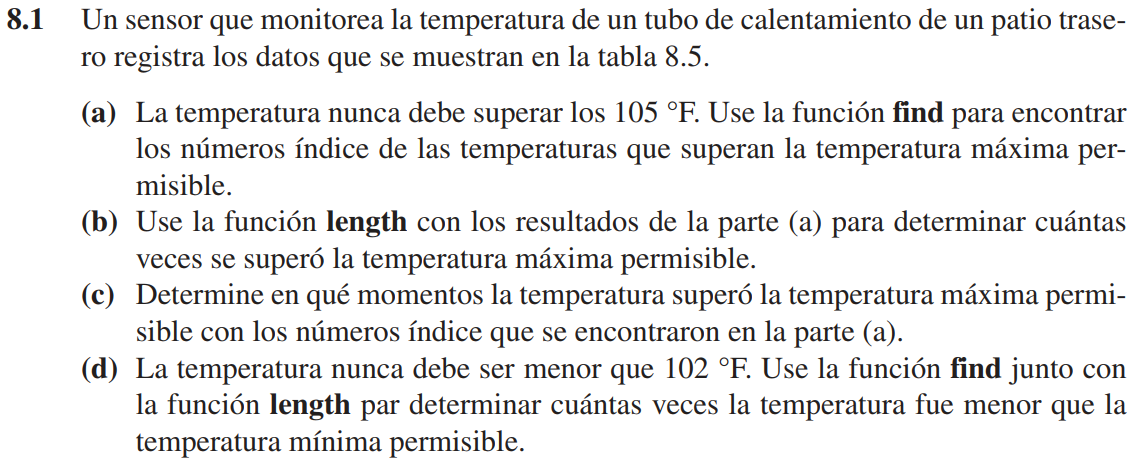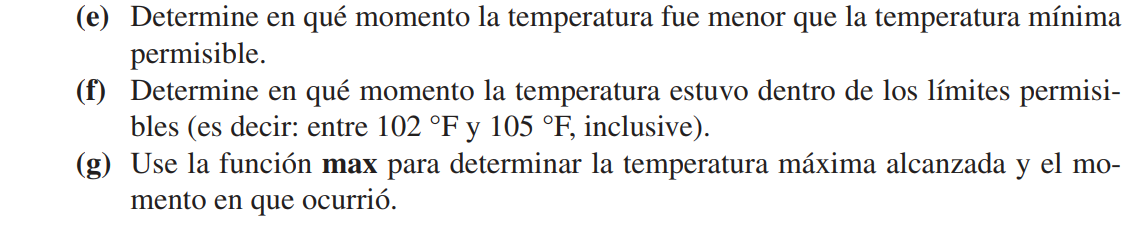

Debido a que la tabla es muy larga, únicamente se copiarán los valores. Ésta se encuentra en la página 289 del libro guía.

% Definir lo que se conoce.
clear

time = 0:24;
temperature = [
    100
    101
    102
    103
    103
    104
    104
    105
    106
    106
    106
    105
    104
    103
    101
    100
    99
    100
    102
    104
    106
    107
    105
    104
    104];
data = [time' temperature];

% Literal a, b, y c.
idxMaxTemperatureValues = find(temperature>105)

numberMaxTemperatures = length(idxMaxTemperatureValues)

timeMaxTemperatures = data(idxMaxTemperatureValues,1)

% Literal d y e.
idxMinTemperatureValues = find(temperature<102)

numberMinTemperature = length(idxMinTemperatureValues)

timeMinTemperatures = data(idxMinTemperatureValues,1)

% Literal f y g.
permisibleTemperatures = find(temperature>=102 & temperature<=105)

timePermisibleTemperatures = data(permisibleTemperatures,1)

maxTemperatureIndex = find(temperature == max(temperature))

timeMaxTemperature = data(maxTemperatureIndex,1)

fprintf('La temperatura máxima es %.1f °F y sucedió a las %d horas.', ...
    max(temperature),timeMaxTemperature)

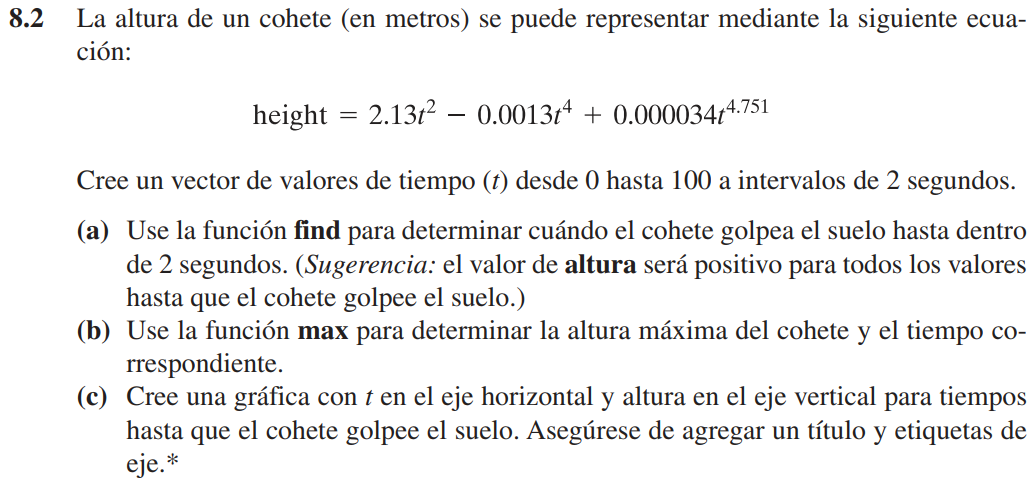

% Se define lo que se conoce.
clear

t = 0:2:100;
h = 2.13*t.^2 - .0013*t.^4 + .000034*t.^4.751;

data = [t' h']

% Todos los literales.
impactTime = t(find(h<=2))

maxHeight = max(h)

timeMaxHeight = t(find(h==max(h)))

fprintf('La altura máxima es %.2f m y ocurre a los %.1f segundos.',maxHeight,timeMaxHeight)

heightPositive = h(find(h>=0));
timeHeightPositive = t(find(h>=0));

plot(timeHeightPositive,heightPositive)
     title 'Altura de un cohete'
     xlabel 'Tiempo, s'
     ylabel 'Altura, m'
     grid

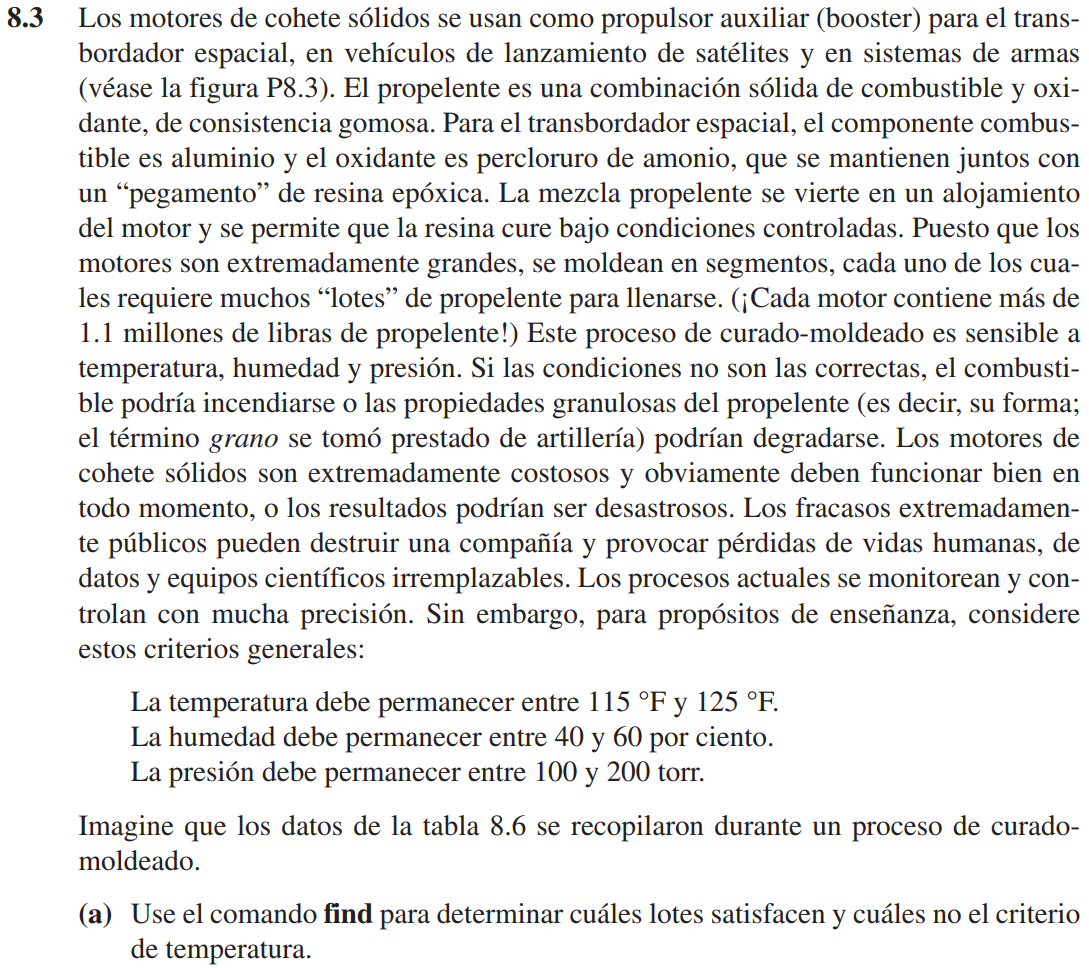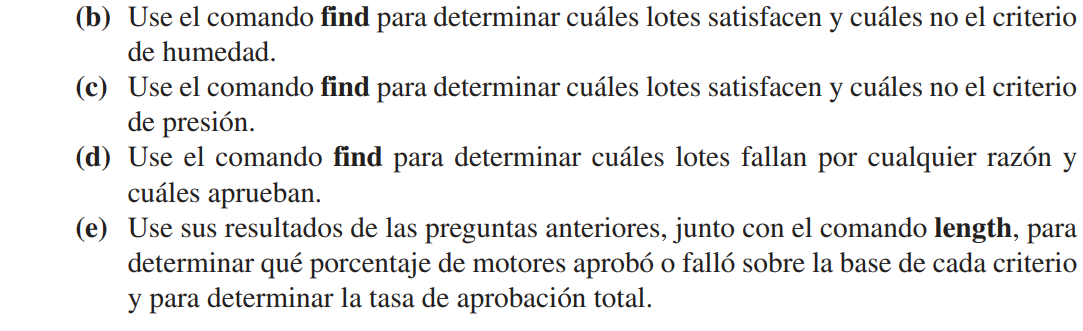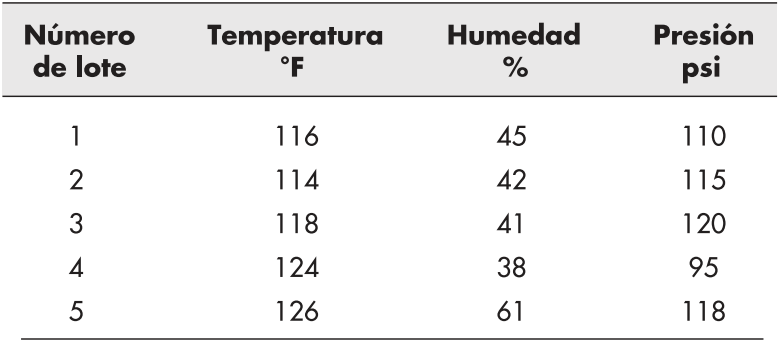

% Se define lo que se conoce.
clear

data = [
    1 116 45 110
    2 114 42 115
    3 118 41 120
    4 124 38 95
    5 126 61 118
    ];

% Literal a.
verifiedTemperature = find(data(:,2)>115 & data(:,2)<125);
unverifiedTemperature = find(~(data(:,2)>115 & data(:,2)<125));
temperatureBatchAccepted = data(verifiedTemperature,1);
temperatureBatchRejected = data(unverifiedTemperature,1);

% Literal b.
verifiedHumidity = find(data(:,3)>40 & data(:,3)<60);
unverifiedHumidity = find(~(data(:,3)>40 & data(:,3)<60));
humidityBatchAccepted = data(verifiedHumidity,1);
humidityBatchRejected = data(unverifiedHumidity,1);

% Literal c.
verifiedPressure = find(data(:,4)>100 & data(:,4)<200);
unverifiedPressure = find(~(data(:,4)>100 & data(:,4)<200));
pressureBatchAccepted = data(verifiedPressure,1);
pressureBatchRejected = data(unverifiedPressure,1);

% Literal d.
verifiedBatch = find(data(:,2)>115 & data(:,2)<125 & data(:,3)>40 & data(:,3)<60 & ...
    data(:,4)>100 & data(:,4)<200);
unverifiedBatch = find(~(data(:,2)>115 & data(:,2)<125 & data(:,3)>40 & data(:,3)<60 & ...
    data(:,4)>100 & data(:,4)<200));
batchAccepted = data(verifiedBatch,1);
batchRejected = data(unverifiedBatch,1);

% Literal e.
percentAcceptedTemp = 100*length(temperatureBatchAccepted)/length(data(:,1));
percentRejectedTemp = 100*length(temperatureBatchRejected)/length(data(:,1));

percentAcceptedHum = 100*length(humidityBatchAccepted)/length(data(:,1));
percentRejectedHum = 100*length(humidityBatchRejected)/length(data(:,1));

percentAcceptedPress = 100*length(pressureBatchAccepted)/length(data(:,1));
percentRejectedPress = 100*length(pressureBatchRejected)/length(data(:,1));

percentLotAccepted = 100*length(batchAccepted)/length(data(:,1));
percentLotRejected = 100*length(batchRejected)/length(data(:,1));

fprintf(['El porcentaje de lotes que satisfacen el criterio de temperatura es %.1f %%\n' ...
    'y el porcentaje que no satisface es %.1f %%.'], ...
    percentAcceptedTemp,percentRejectedTemp)
fprintf(['El porcentaje de lotes que satisfacen el criterio de humedad es %.1f %%\n' ...
    'y el porcentaje que no satisface es %.1f %%.'], ...
    percentAcceptedHum,percentRejectedHum)
fprintf(['El porcentaje de lotes que satisfacen el criterio de presión es %.1f %%\n' ...
    'y el porcentaje que no satisface es %.1f %%.'], ...
    percentAcceptedPress,percentRejectedPress)
fprintf(['El porcentaje de lotes que satisfacen todos los criterios es %.1f %%\n' ...
    'y el porcentaje que no satisface es %.1f %%.'], ...
    percentLotAccepted,percentLotRejected)

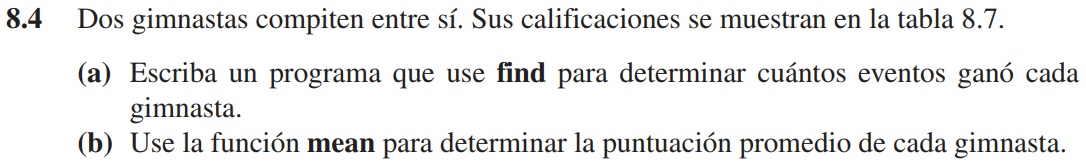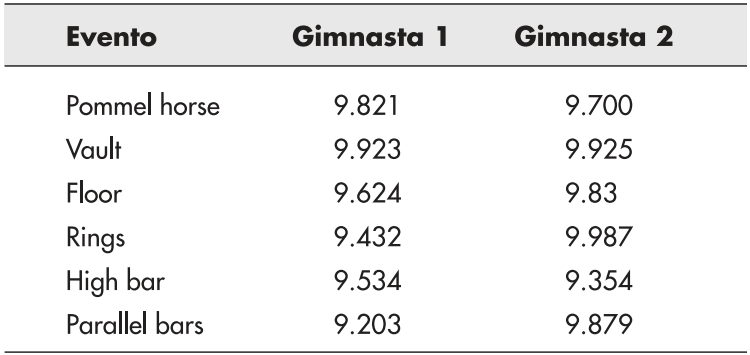

% Se define lo que se conoce.
clear

data = [
    9.821 9.700
    9.923 9.925
    9.624 9.830
    9.432 9.987
    9.534 9.354
    9.203 9.879
    ];

% Literal a y b.
numberWinsGymnast1 = length(find(data(:,1)>data(:,2)))
numberWinsGymnast2 = length(find(data(:,2)>data(:,1)))

meanGymnast1 = mean(data(:,1))
meanGymnast2 = mean(data(:,2))